# Color Calibration

#### Author: Joelle Dowling

#### Created: Autumn 2020

This project aims to model the spectral quantum efficiency of the sensor channels, relating the inputs (spectral radiance) and the outputs (digital camera values).

This will be achieved by using spectral radiance measurements and camera images for three different illuminants, tungsten (A), cool white fluorescent (cwf), and daylight (day).

ieInit; % Initialize ISETCam

### Part 1: Calculating Spectral Signals Matrix

#### Read Spectral Radiance Measurements

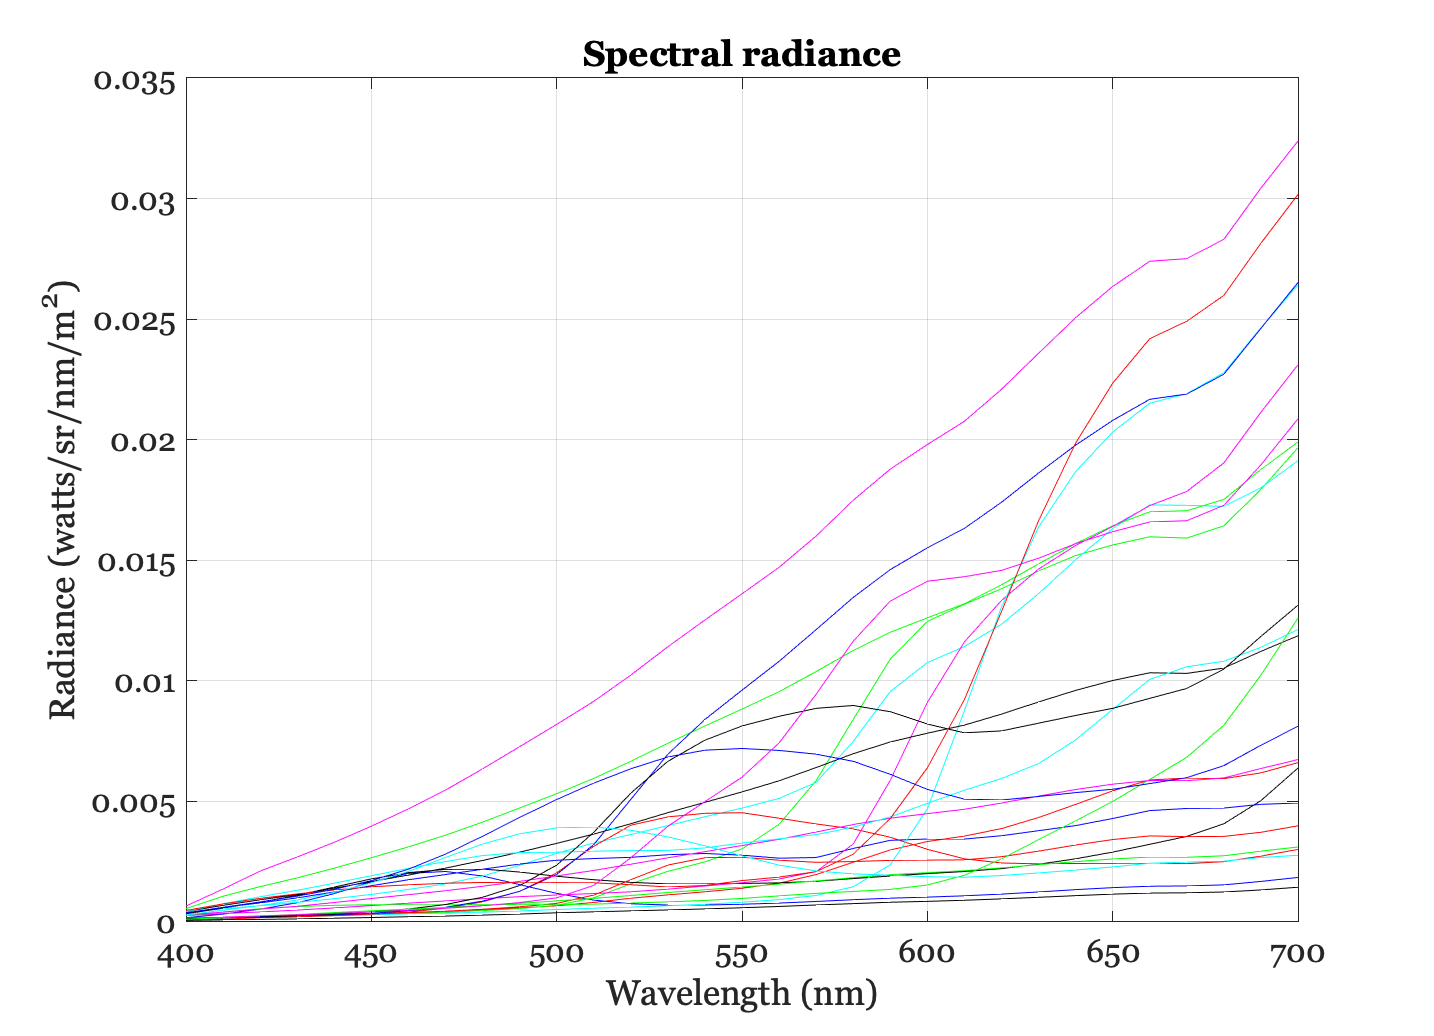

wavelength = 400:10:700;

dataDir = '/Volumes/Wandell/Data Psych 221 Projects/Color calibration/Measurements 1/mccSpectralRadianceAndLights1';

fname = '20201023-mccRadianceData.mat';       % In psych221/projects
dataFile = fullfile(dataDir,fname);
radiance = ieReadSpectra(dataFile, wavelength);

radianceA = radiance(:,1:24);
radianceCWF = radiance(:,25:48);
radianceDay = radiance(:,49:72);

plotRadiance(wavelength,radianceA);    % Illuminant A 

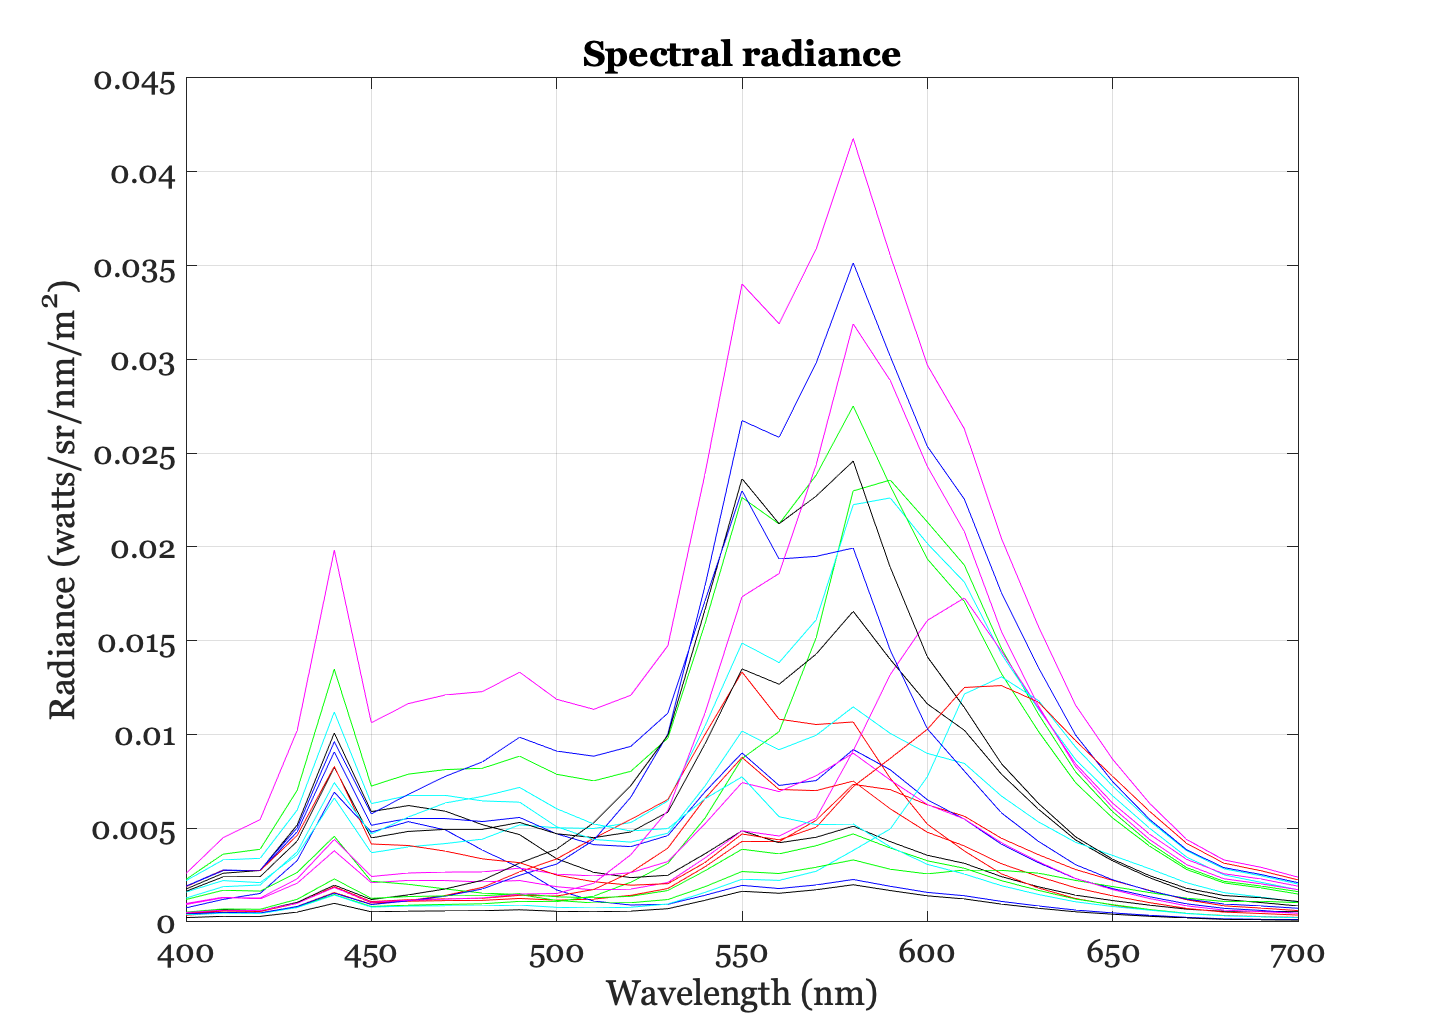

plotRadiance(wavelength,radianceCWF);  % Illuminant CWF

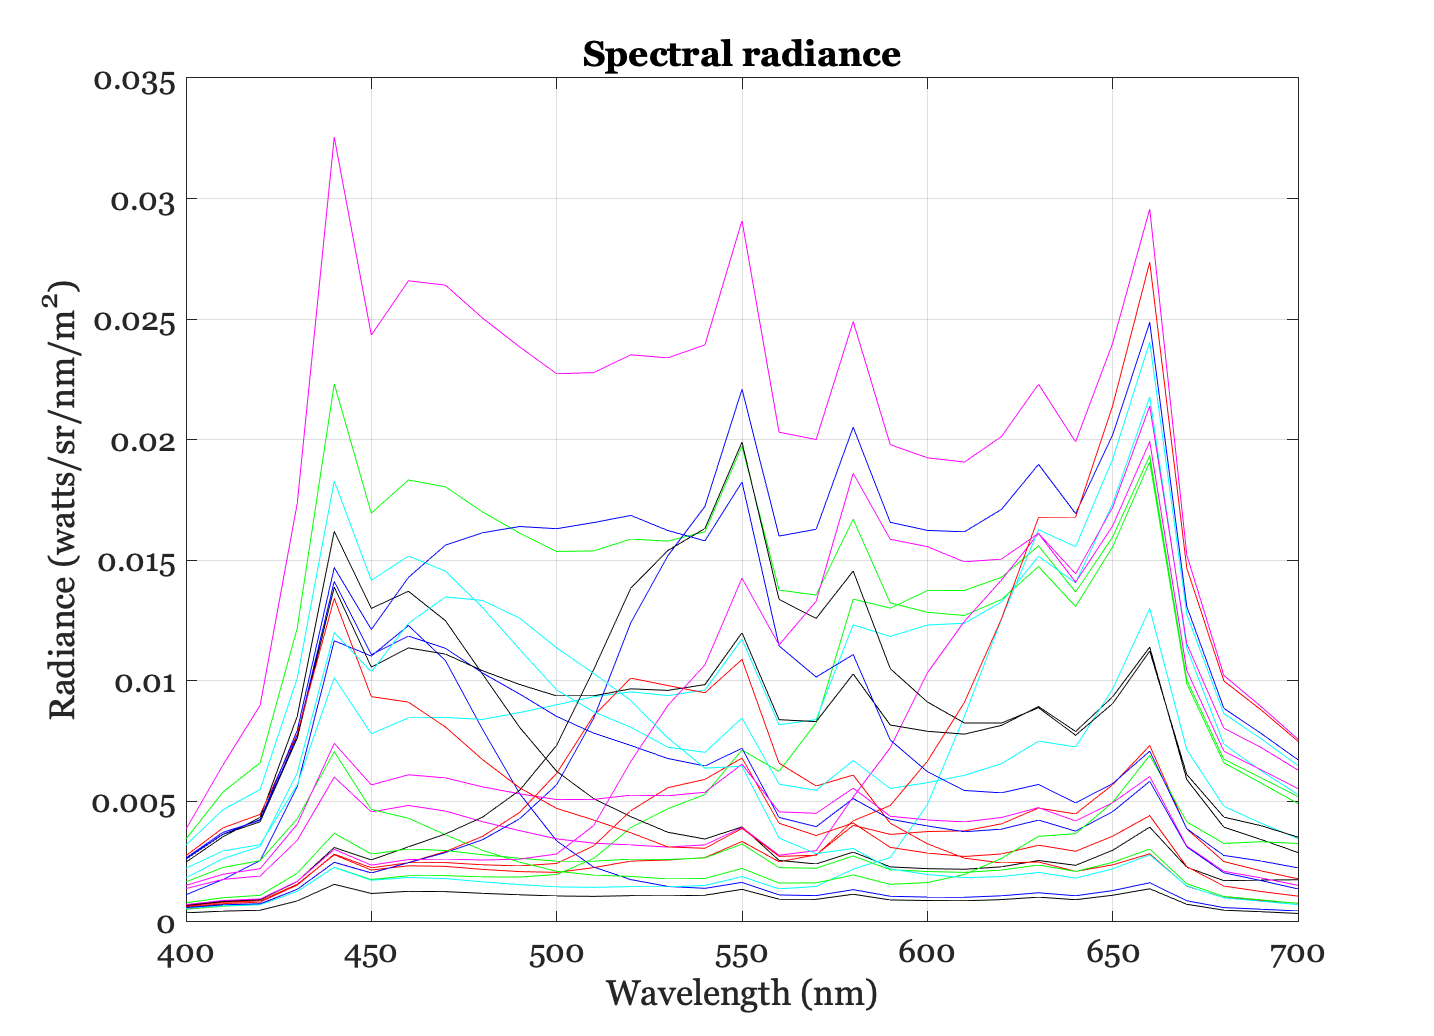

plotRadiance(wavelength,radianceDay);  % Illuminant Day

### Part 2: The RGB values from Google Pixel 4 data (Getting and Correcting)

#### Reading the Camera Sensor Data for each of the three illuminants

dataDir = fullfile(teachRootPath,'local','data','spectralqe','Measurements1','DNG-Illuminant-A');
camera_A = 'IMG_20201024_123128.dng'; % Sensor Data under illuminant A taken from Canvas
chdir(dataDir);

% exist(camera_A,'file')
% img_A = ieDNGRead(camera_A);  % Read the image data 
% [~, info_A] = ieDNGRead(camera_A,'only info',true, 'simple info', true)

% Read in a cropped version of the data
thisRect = [1860  2010  350  255]; %col, row, width, height
[camera_A, info_A] = sensorDNGRead(camera_A,'crop',thisRect);
sensorWindow(camera_A);

#### Select cornerpoints in Sensor Window

% Select the corner points
cpA = chartCornerpoints(camera_A);   % Select corners
%{
cpA = [
    38   222
   316   224
   314    41
    40    40];
%}

### Extract the RGB data from the MCC

blackBorder = true;  % Estimate rectangles

Black border


[rects, mLocs, pSize] = chartRectangles(cpA,4,6,0.5,blackBorder);
chartRectsDraw(camera_A,rects);  % Visualize the rectangles

% Get only the mean values from each patch
nPixels = round(pSize(1)/4);  % Choose a fraction of the pixels in the patch
fullData = true;             % Return only the mean
dvalues = chartRectsData(camera_A,mLocs,nPixels,fullData,'dv'); %returns digital values

#### Find mean and standard deviation

rgb_mean_A = zeros(24,3);
rgb_std_A = rgb_mean_A;
for ii = 1:24
    rgb_mean_A(ii,:) = nanmean(dvalues{ii});
    rgb_std_A(ii,:)  = nanstd(dvalues{ii});
end

#### Correct RGB values for Black Level and Exposure Time

Correction of the RGB values was done 4 different ways to decide on the best one. The first and third ways give similarly shaped sensor sensitivities, but with different scales. The second and fourth ways gave worse results than the first and third, getting negative RGB values and having all the channel's responsivity overlapping. 

rgb_corrected_A = (rgb_mean_A-info_A.BlackLevel(1))./info_A.ExposureTime;

We are solving for spectral QE, in the columns of a matrix.  The radiance data are also in the columns.  So we multiple the transpose of radiance times the spectral QE to determine the correted RGB values.  We will solve for the spectral QE in various ways, including the pseudo-inverse and methods that force the solution to be a smooth function of wavelength.


$$\begin{array}{l}
\mathrm{rgb}={{\mathrm{radiance}}^{\prime } *\mathrm{spectralQE}}^{\prime } \\
\mathrm{spectralQE}\;=\;\mathrm{pinv}\left({\mathrm{radiance}}^{\prime } \right)*\mathrm{rgb}
\end{array}$$


spectralQE = pinv(radianceA')*rgb_corrected_A;
ieNewGraphWin;
plot(wavelength,spectralQE)

pred = radianceA'*spectralQE;
ieNewGraphWin;
plot(pred(:),rgb_corrected_A(:),'o');
identityLine;

#### Reading Camera Sensor Data for Illuminant cwf

dataDir = fullfile(teachRootPath,'local','data','spectralqe','Measurements1','DNG-Illuminant-CWF');
chdir(dataDir);
camera_cwf = 'IMG_20201024_122900.dng'; % Sensor Data under illuminant cwf taken from Canvas
thisRect = [1860  2010  370  290]; %col, row, width, height
[camera_cwf, info_cwf] = sensorDNGRead(camera_cwf,'crop',thisRect);
sensorWindow(camera_cwf);

#### Select cornerpoints in Sensor window

cpCWF = chartCornerpoints(camera_cwf);   % Select corners
cpCWF
%{
cpCWF = [
    62   218
   337   222
   337    38
    63    37]
%}

blackBorder = true;  % Estimate rectangles
[rects, mLocs, pSize] = chartRectangles(cpCWF,4,6,0.5,blackBorder);

Black border


chartRectsDraw(camera_cwf,rects);  % Visualize the rectangles
nPixels = round(pSize(1)/4);  % Choose a fraction of the pixels in the patch
fullData = true;             % Return only the mean
dvalues = chartRectsData(camera_cwf,mLocs,nPixels,fullData,'dv'); %returns digital values

#### Find mean and standard deviation

rgb_mean_cwf = zeros(24,3);
rgb_std_cwf  = zeros(24,3);
for ii = 1:24
    rgb_mean_cwf(ii,:) = nanmean(dvalues{ii});
    rgb_std_cwf(ii,:) = nanstd(dvalues{ii});
end

#### Correct RGB values for Black Level and Exposure Time

See explanation for four methods in the corresponding section for Illuminant A

rgb_corrected_cwf = (rgb_mean_cwf-info_cwf.BlackLevel(1))./info_cwf.ExposureTime;

### Try this one alone, and then in combination with A

spectralQE = pinv(radianceCWF')*rgb_corrected_cwf;
ieNewGraphWin;
plot(wavelength,spectralQE)

pred = radianceCWF'*spectralQE;
ieNewGraphWin;
plot(pred(:),rgb_corrected_cwf(:),'o');
identityLine;

Combine them.  Still not there.

radiance = [radianceA, radianceCWF];
rgb = [rgb_corrected_A; rgb_corrected_cwf];
spectralQE = pinv(radiance')*rgb;

ieNewGraphWin;
plot(wavelength,spectralQE)

pred = radiance'*spectralQE;
ieNewGraphWin;
plot(pred(:),rgb(:),'o');
identityLine;

#### Reading and Correcting Camera Sensor Data for Illuminant day

dataDir = fullfile(teachRootPath,'local','data','spectralqe','Measurements1','DNG-Illuminant-Day');
chdir(dataDir);
camera_day = 'IMG_20201024_122631.dng'; % Sensor data for illuminant day taken from Canvas
thisRect = [1860  2010  370  290]; %col, row, width, height

info_day = struct with fields:
        isoSpeed: 55
    exposureTime: 0.0083
      blackLevel: [63.9300 63.9300 63.8700 63.8700]
     orientation: 1


[camera_day, info_day] = sensorDNGRead(camera_day,'crop',thisRect);
sensorWindow(camera_day);

#### Select cornerpoints in Sensor Window

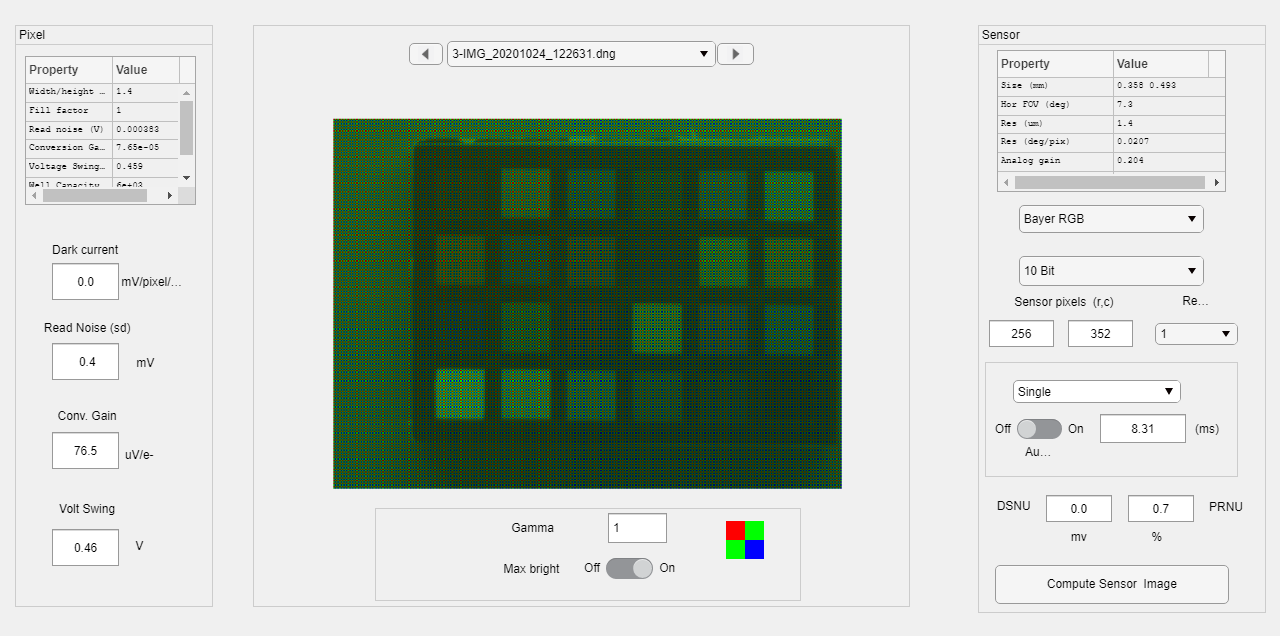

cpDay = chartCornerpoints(camera_day);   % Select corners

cpDay
%{
cpDay = [
    73   218
   344   222
   344    39
    73    36];
%}
blackBorder = true;  % Estimate rectangles
[rects, mLocs, pSize] = chartRectangles(cpDay,4,6,0.5,blackBorder);

Black border


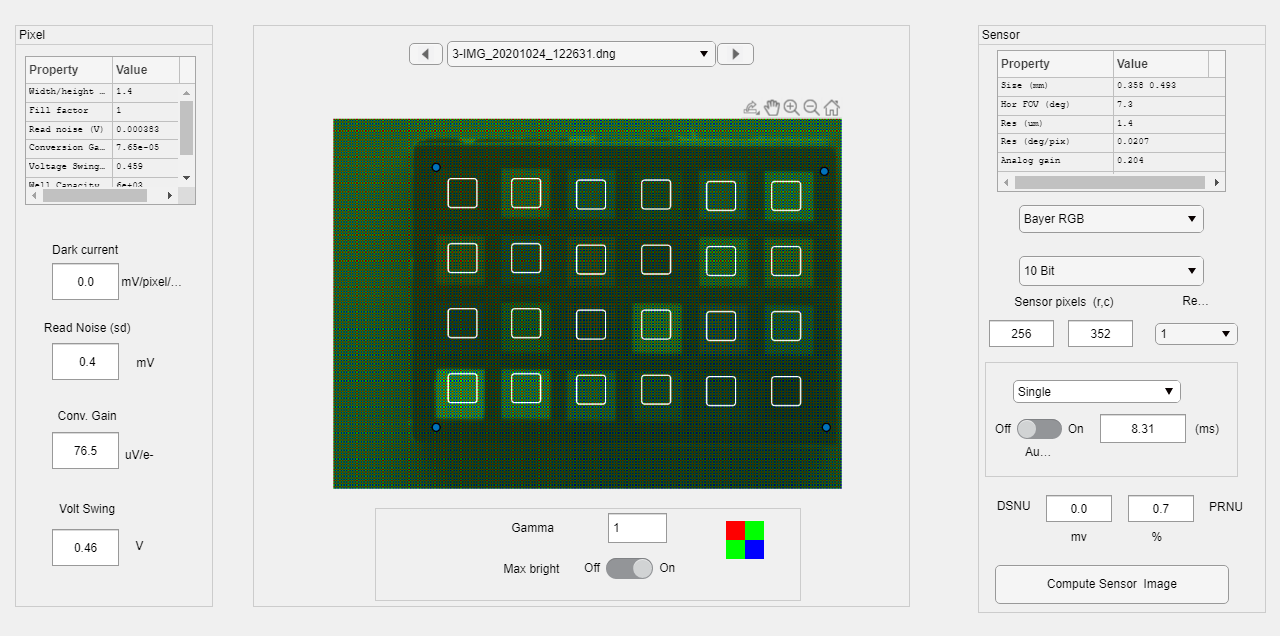

chartRectsDraw(camera_day,rects);  % Visualize the rectangles

nPixels = round(pSize(1)/4);  % Choose a fraction of the pixels in the patch
fullData = true;             % Return only the mean
dvalues = chartRectsData(camera_day,mLocs,nPixels,fullData,'dv'); %returns digital values

#### Find mean and standard deviation

rgb_mean_day = zeros(24,3);
rgb_std_day = zeros(24,3);
for ii = 1:24
    rgb_mean_day(ii,:) = nanmean(dvalues{ii});
    rgb_std_day(ii,:) = nanstd(dvalues{ii});
end

#### Correct RGB values for Black Level, IsoSpeed, and Exposure Time

rgb_corrected_day = (rgb_mean_day-info_day.BlackLevel(1))./info_day.ExposureTime;

#### Putting together all the RGB values

Concatenating the corrected RGB matrices into one matrix

radiance = [radianceA, radianceCWF, radianceDay];
rgb = [rgb_corrected_A; rgb_corrected_cwf; rgb_corrected_day];
spectralQE = pinv(radiance')*rgb;

ieNewGraphWin;
plot(wavelength,spectralQE)

pred = radiance'*spectralQE;
ieNewGraphWin;
plot(pred(:),rgb(:),'o');
identityLine;

## Check the sensor itself

### Part 3: Calculating the Sensor Spectral Sensitivty

Now that we have the reflectance matrix and the RGB values, we can solve for the Spectral Sensitivity of the sensor.

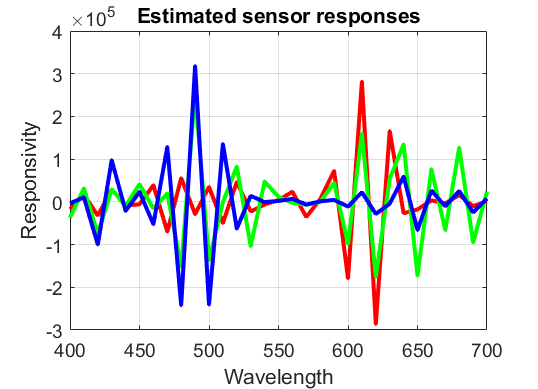

estimate = (rgb_corrected/spectral_signals)';

ieNewGraphWin;
plot(wavelength,estimate(:,1),'r',  ...
     wavelength,estimate(:,2),'g', ...
     wavelength,estimate(:,3),'b', 'LineWidth',2)
grid on
xlabel('Wavelength'), ylabel('Responsivity')
title('Estimated sensor responses')

Check with Sony Characterization

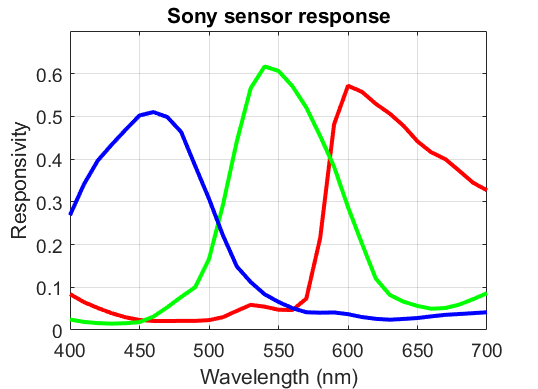

spectralQE = ieReadSpectra('qe_IMX363_public.mat', wavelength);
plot(wavelength(:), spectralQE(:,1),'r',...
    wavelength(:),spectralQE(:,2),'g', ...
    wavelength(:),spectralQE(:,3),'b','LineWidth',2); grid on
xlabel('Wavelength (nm)'); ylabel('Responsivity')
title('Sony sensor response')


predRGB = radiance'*spectralQE;
predRGBs = ieScale(predRGB,1);
rgbs = ieScale(rgb,1);
ieNewGraphWin;

plot(predRGBs,rgbs,'o');
identityLine;

Calculate the number of PCs in the radiance data

[U,S,V] = svd(radiance);
% Use the first ten or so columns of U as the potential solution
ieNewGraphWin;
plot(U(:,1:10))

Suppose spectralQE is always

spectralQE = thisB*w;

rgb = radiance'*spectralQE = radiance'*thisB*w

w = pinv(radiance'*thisB)*rgb;

spectralQE = thisB*w;

thisB = U(:,1:6);
w = pinv(radiance'*thisB)*rgb;
spectralQE = thisB*w;
ieNewGraphWin;
plot(wavelength,spectralQE)

### Checking RGB Values

Compare the RGB values from our calculation to the RGB values calculated with the Sony Sensor Characterization

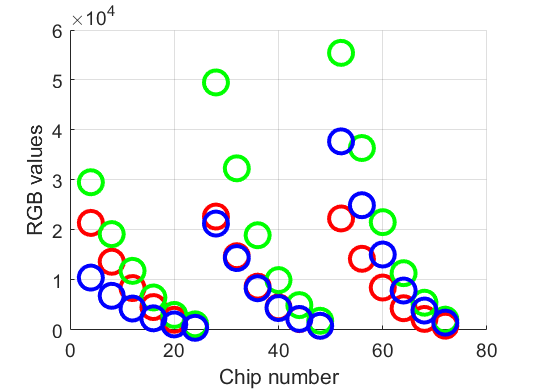

rgbResponses = sensors'*spectral_signals;
graySeries = 4:4:72; 
ieNewGraphWin; hold on;
plot(graySeries,rgb_corrected(1,graySeries)','ro', 'MarkerSize',12,'LineWidth',2); hold on;
plot(graySeries,rgb_corrected(2,graySeries)','go', 'MarkerSize',12,'LineWidth',2); hold on;
plot(graySeries,rgb_corrected(3,graySeries)','bo', 'MarkerSize',12,'LineWidth',2); 
grid on;
xlabel('Chip number'); ylabel('RGB values');

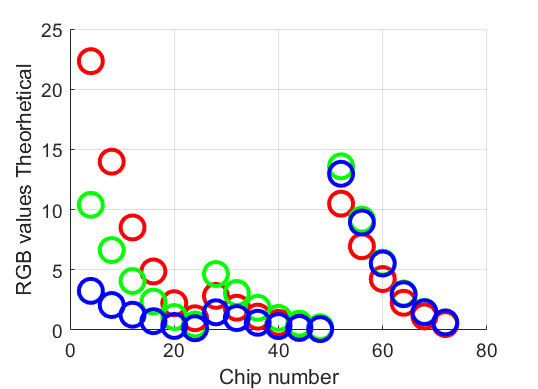


ieNewGraphWin; hold on;
plot(graySeries,rgbResponses(1,graySeries)','ro', 'MarkerSize',12,'LineWidth',2); hold on;
plot(graySeries,rgbResponses(2,graySeries)','go', 'MarkerSize',12,'LineWidth',2); hold on;
plot(graySeries,rgbResponses(3,graySeries)','bo', 'MarkerSize',12,'LineWidth',2); 
grid on;
xlabel('Chip number'); ylabel('RGB values Theorhetical');

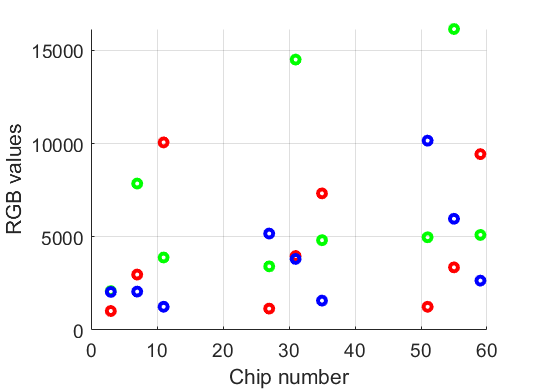

blueChip = 3:24:51; greenChip = 7:24:55; redChip = 11:24:59; 
ieNewGraphWin; hold on;
plot(greenChip, rgb_corrected(1, greenChip)', 'ro', 'MarkerSize',4,'LineWidth',2);hold on;
plot(greenChip, rgb_corrected(2, greenChip)', 'go', 'MarkerSize',4,'LineWidth',2);hold on;
plot(greenChip, rgb_corrected(3, greenChip)', 'bo', 'MarkerSize',4,'LineWidth',2);hold on;
plot(blueChip, rgb_corrected(1, blueChip)', 'ro', 'MarkerSize',4,'LineWidth',2);hold on;
plot(blueChip, rgb_corrected(2, blueChip)', 'go', 'MarkerSize',4,'LineWidth',2);hold on;
plot(blueChip, rgb_corrected(3, blueChip)', 'bo', 'MarkerSize',4,'LineWidth',2);hold on;
plot(redChip, rgb_corrected(1, redChip)', 'ro', 'MarkerSize',4,'LineWidth',2);hold on;
plot(redChip, rgb_corrected(2, redChip)', 'go', 'MarkerSize',4,'LineWidth',2);hold on;
plot(redChip, rgb_corrected(3, redChip)', 'bo', 'MarkerSize',4,'LineWidth',2);hold on;
grid on;
xlabel('Chip number'); ylabel('RGB values');

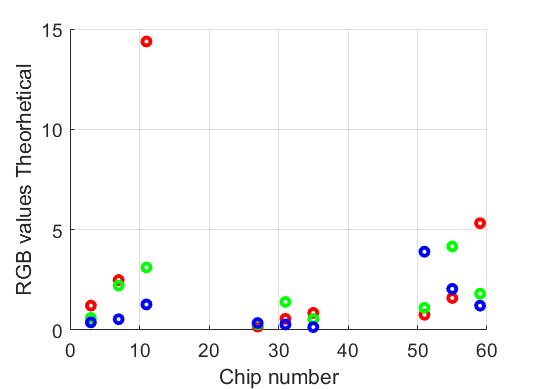


ieNewGraphWin; hold on;
plot(greenChip, rgbResponses(1, greenChip)', 'ro', 'MarkerSize',4,'LineWidth',2);hold on;
plot(greenChip, rgbResponses(2, greenChip)', 'go', 'MarkerSize',4,'LineWidth',2);hold on;
plot(greenChip, rgbResponses(3, greenChip)', 'bo', 'MarkerSize',4,'LineWidth',2);hold on;
plot(blueChip, rgbResponses(1, blueChip)', 'ro', 'MarkerSize',4,'LineWidth',2);hold on;
plot(blueChip, rgbResponses(2, blueChip)', 'go', 'MarkerSize',4,'LineWidth',2);hold on;
plot(blueChip, rgbResponses(3, blueChip)', 'bo', 'MarkerSize',4,'LineWidth',2);hold on;
plot(redChip, rgbResponses(1, redChip)', 'ro', 'MarkerSize',4,'LineWidth',2);hold on;
plot(redChip, rgbResponses(2, redChip)', 'go', 'MarkerSize',4,'LineWidth',2);hold on;
plot(redChip, rgbResponses(3, redChip)', 'bo', 'MarkerSize',4,'LineWidth',2);hold on;
grid on;
xlabel('Chip number'); ylabel('RGB values Theorhetical');

## Measurements 2

Now repeating the above process for the second set of measurements, with separate radiance files

### Part 1: Calculating Spectral Signals Matrix

#### Read Spectral Radiance Measurements

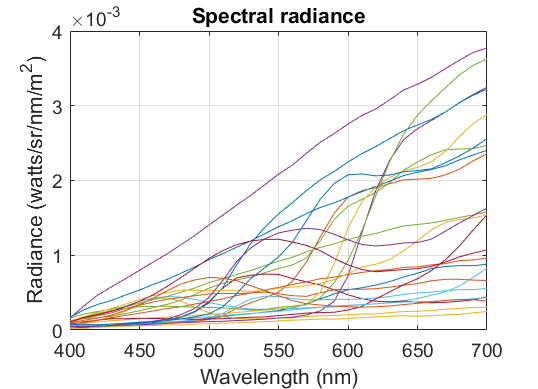

ans =   Figure (15: ISET GraphWin) with properties:

      Number: 15
        Name: 'ISET GraphWin'
       Color: [1 1 1]
    Position: [0.0070 0.5500 0.2800 0.3600]
       Units: 'normalized'

  Show all properties


rad(:,1) = ieReadSpectra('11-brown-studio-1.mat', wavelength);
rad(:,5) = ieReadSpectra('12-tan-studio-1.mat', wavelength);
rad(:,9) = ieReadSpectra('13-skyblue-studio-1.mat', wavelength);
rad(:,13) = ieReadSpectra('14-darkgreen-studio-1.mat', wavelength);
rad(:,17) = ieReadSpectra('15-lightpurple-studio-1.mat', wavelength);
rad(:,21) = ieReadSpectra('16-turquoise-studio-1.mat', wavelength);
rad(:,2) = ieReadSpectra('21-orange-studio-1.mat', wavelength);
rad(:,6) = ieReadSpectra('22-lightblue-studio-1.mat', wavelength);
rad(:,10) = ieReadSpectra('23-pink-studio-1.mat', wavelength);
rad(:,14) = ieReadSpectra('24-purple-studio-1.mat',wavelength);
rad(:,18) = ieReadSpectra('25-lime-studio-1.mat', wavelength);
rad(:,22) = ieReadSpectra('26-mustard-studio-1.mat', wavelength);
rad(:,3) = ieReadSpectra('31-blue-studio-1.mat', wavelength);
rad(:,7) = ieReadSpectra('32-green-studio-1.mat', wavelength);
rad(:,11) = ieReadSpectra('33-red-studio-1.mat', wavelength);
rad(:,15) = ieReadSpectra('34-yellow-studio-1.mat', wavelength);
rad(:,19) = ieReadSpectra('35-magenta-studio-1.mat', wavelength);
rad(:,23) = ieReadSpectra('36-cyan-studio-1.mat', wavelength);
rad(:,4) = ieReadSpectra('41-white-studio-1.mat', wavelength);
rad(:,8) = ieReadSpectra('42-gray-studio-1.mat', wavelength);
rad(:,12) = ieReadSpectra('43-gray-studio-1.mat', wavelength);
rad(:,16) = ieReadSpectra('44-gray-studio-1.mat', wavelength);
rad(:,20) = ieReadSpectra('45-gray-studio-1.mat', wavelength);
rad(:,24) = ieReadSpectra('46-black-studio-1.mat', wavelength);

plotRadiance(wavelength, rad)

spec_sig = diag(illum_A)*rad;

### Part 2: The RGB values from Google Pixel 4 data (Getting and Correcting)

cam_1 = 'IMG_20201027_173455.dng'; % Sensor Data under illuminant A

img_1 = ieDNGRead(cam_1);  % Read the image data 
[~, info_1] = ieDNGRead(cam_1,'only info',true, 'simple info', true)

info_1 = struct with fields:
        isoSpeed: 55
    exposureTime: 0.0285
      blackLevel: [63.9300 63.9300 63.8700 63.8700]
     orientation: 3



cropRect = [2110,935,165,120]; %col, row, width, height
[cam_1, info_1] = sensorDNGRead(cam_1,'crop',cropRect);
% [cam_1, info_1] = sensorDNGRead(cam_1)
sensorWindow(cam_1);

Select cornerpoints

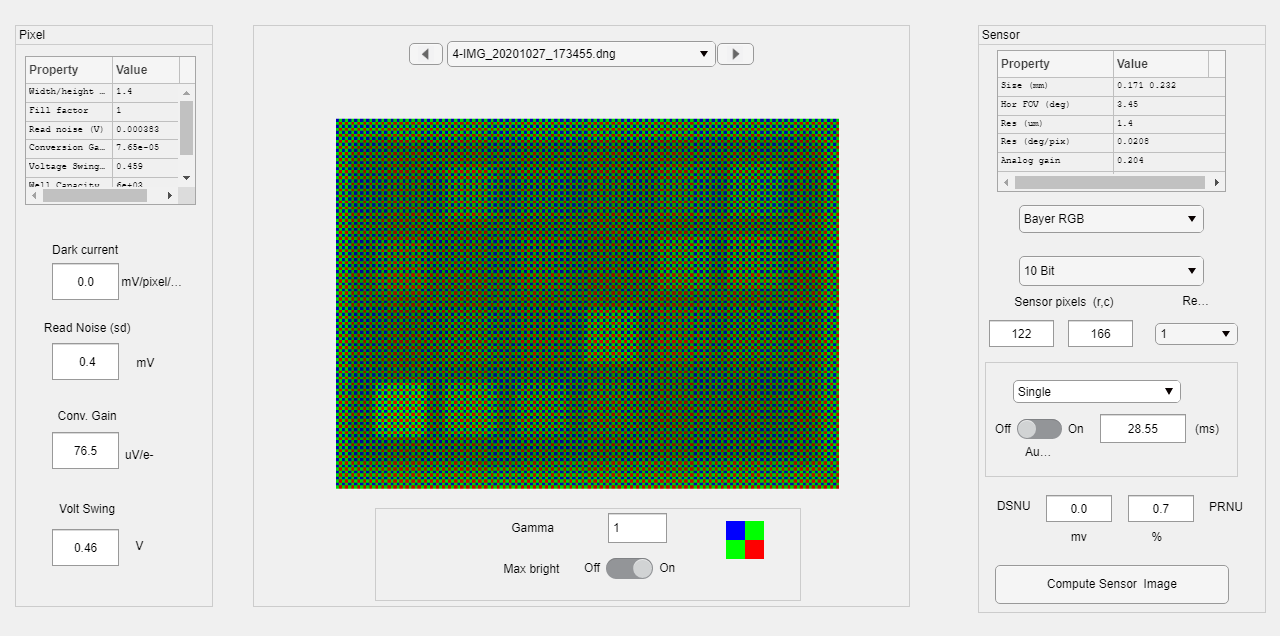

cp = chartCornerpoints(cam_1);   % Select corners


blackBorder = true;  % Estimate rectangles
[rects, mLocs, pSize] = chartRectangles(cp,4,6,0.5,blackBorder);

Black border


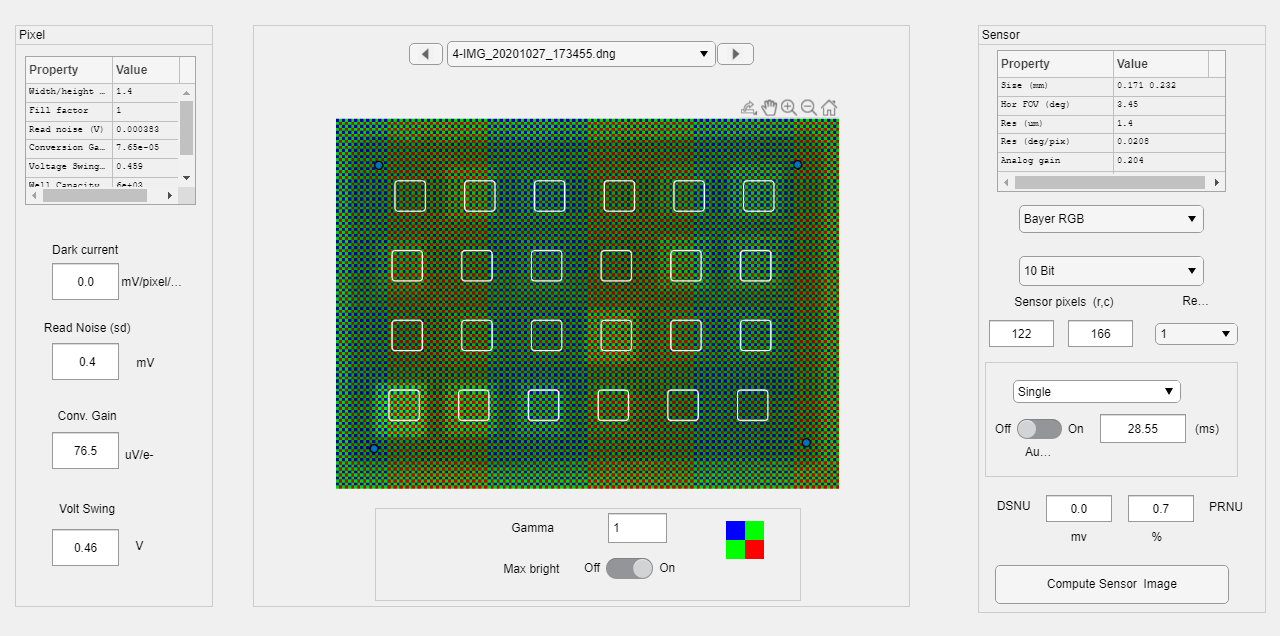


chartRectsDraw(cam_1,rects);  % Visualize the rectangles


nPixels = round(pSize(1)/5);  % Choose a fraction of the pixels in the patch
fullData = true;             % Return only the mean
dvalues = chartRectsData(cam_1,mLocs,nPixels,fullData,'dv');

Find mean and standard deviation

for ii = 1:24
    rgb_mean_1(:,ii) = nanmean(dvalues{ii});
    rgb_std_1(:,ii) = nanstd(dvalues{ii});
end

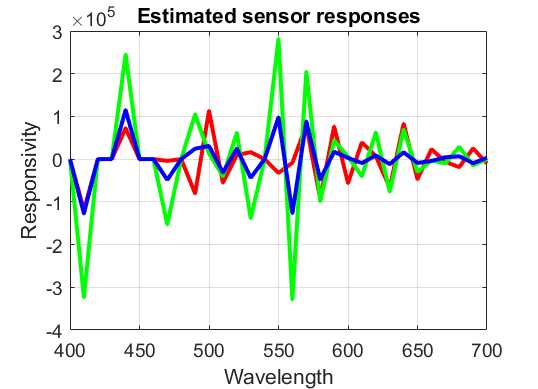


rgb_corrected_1 = (rgb_mean_1-info_1.BlackLevel(1))./info_1.ExposureTime;
estimate = (rgb_corrected_1/(spec_sig))';

ieNewGraphWin;
plot(wavelength,estimate(:,1),'r',  ...
     wavelength,estimate(:,2),'g', ...
     wavelength,estimate(:,3),'b', 'LineWidth',2)
grid on
xlabel('Wavelength'), ylabel('Responsivity')
title('Estimated sensor responses')

#### Illuminant Spectral Power Distribution

Tungsten

illum_A = ieReadSpectra('illuminantA.mat', wavelength);
ieNewGraphWin;
plot(wavelength,illum_A,'b','LineWidth',2); grid on
xlabel('Wavelength (nm)');
ylabel('Energy');
title('Spectral radiance energy of Tungsten illuminant (relative)');

Cool White Fluorescent 

illum_cwf = ieReadSpectra('Fluorescent2.mat', wavelength);
ieNewGraphWin;
plot(wavelength,illum_cwf,'b','LineWidth',2); grid on
xlabel('Wavelength (nm)');
ylabel('Energy');
title('Spectral radiance energy of Fluorescent illuminant (relative)');

Daylight

illum_day = ieReadSpectra('D65.mat', wavelength);
ieNewGraphWin;
plot(wavelength,illum_day,'b','LineWidth',2); grid on
xlabel('Wavelength (nm)');
ylabel('Energy');
title('Spectral radiance energy of Daylight (relative)');



#### Multiplying the illuminant and surface radiance to get reflectance

Spectral Signals for individual illuminants

spec_sig_A = diag(illum_A)*radiance(:,1:24);
spec_sig_cwf = diag(illum_cwf)*radiance(:,25:48);
spec_sig_day = diag(illum_day)*radiance(:,49:72);

% As examples, plot the spectral signal scattered from the green and
% gray Macbeth surfaces.
ieNewGraphWin;
plot(wavelength,spec_sig_day(:,7),'g'); hold on
plot(wavelength,spec_sig_day(:,8),'k');  
plot(wavelength,spec_sig_day(:,3),'b');hold off
xlabel('Wavelength (nm)'); ylabel('Reflected Energy');
title('Reflected energy of surfaces under D65')
legend('Green scatter','Gray scatter','Blue scatter')
grid on

Full Spectral Signal Matrix

spectral_signals = [spec_sig_A spec_sig_cwf spec_sig_day]